# Get orientation of images

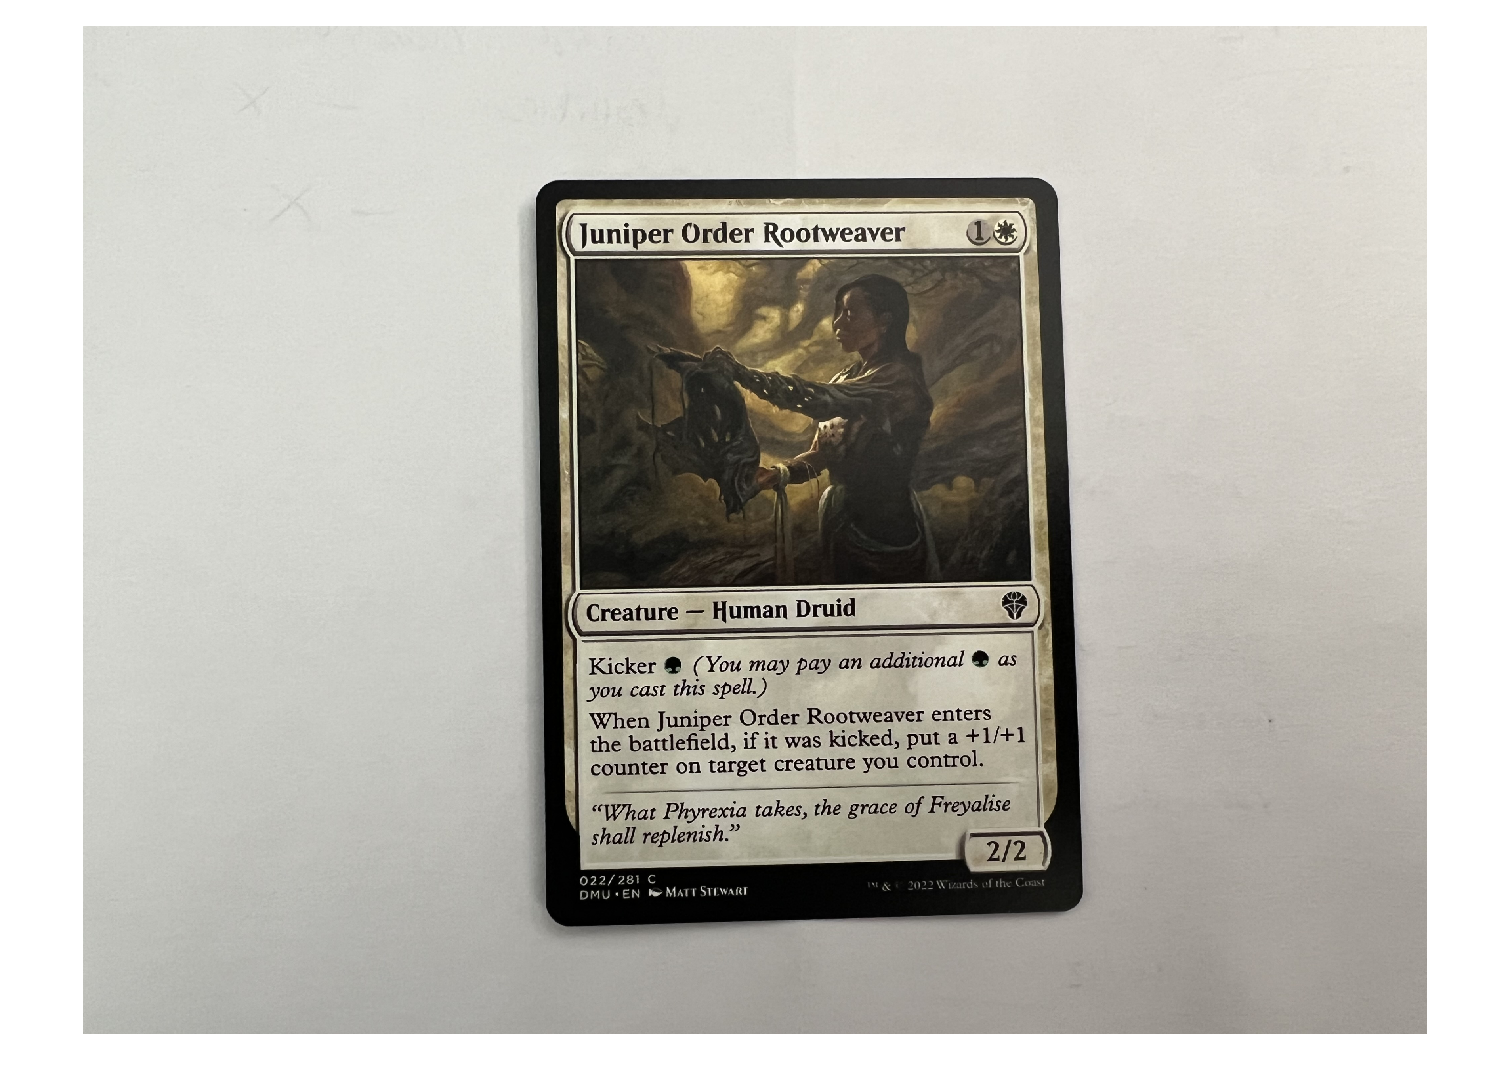

folderPath = 'C:\Users\Josef\Downloads\MTG-Card-Recognition-main (2)\MTG-Card-Recognition-main\dmuset_cards';
file_list = dir(fullfile(folderPath, '*.JPG'));

% Loop through the list of files and display each image
for i = 1:numel(file_list)
    % Read the image from file
    image_data = imread(fullfile(folderPath, file_list(i).name));
    
    % Display the image
    imshow(image_data)
    
    % Pause to allow time to view the image (optional)
    %pause(1);
end

# standardize card image

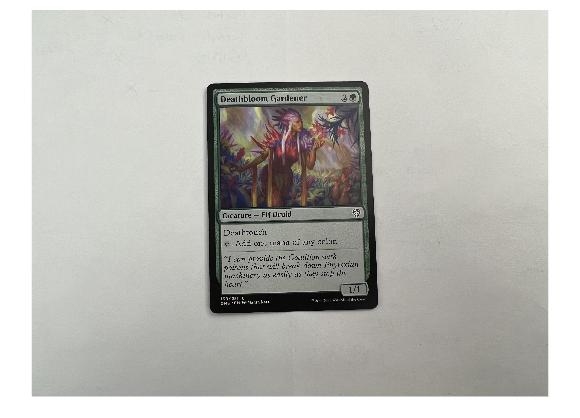

realImg = imread("dmuset_cards/deathbloom_-.JPG");
ogImg = realImg;
figure;
imshow(realImg);

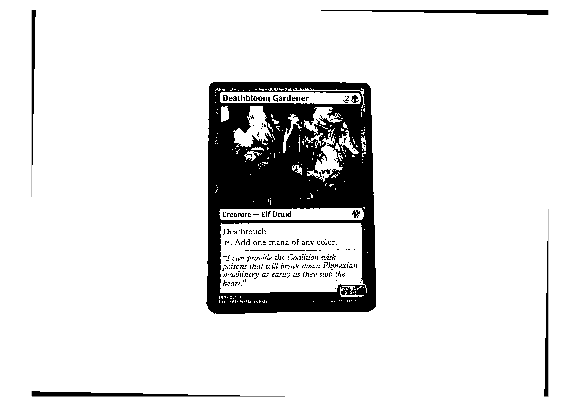


realImg = rgb2gray(realImg);
realImg = medfilt2(realImg);
realImg = imbinarize(realImg,graythresh(realImg));


[h,l,t] = hough(edge(realImg,"sobel"));
peaks = houghpeaks(h,1);
lines = houghlines(edge(realImg,"sobel"),l,t,peaks);

angle = atan2(lines(1).point2(2)-lines(1).point1(2),lines(1).point2(1)-lines(1).point1(1));
corrected = imrotate(realImg,rad2deg(angle),'bilinear','crop');

figure;
imshow(corrected);

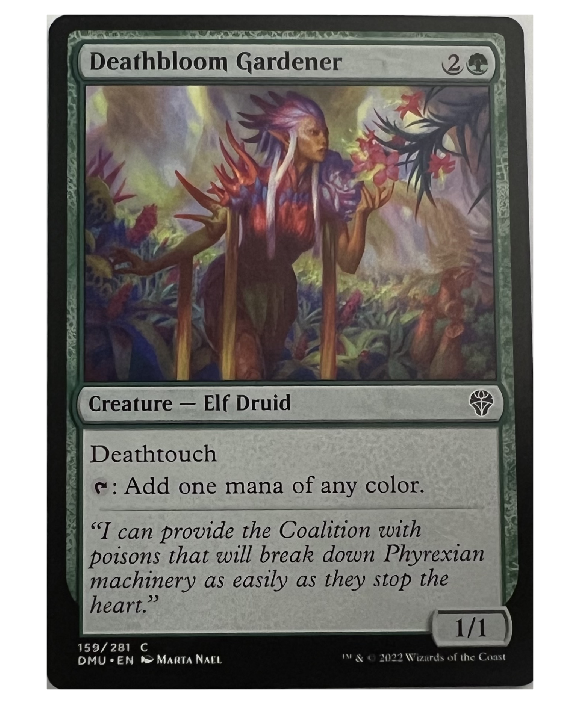


[r,c] = size(corrected);


northmost = r;
southmost = 1;
westmost = c;
eastmost = 1;

for i=r/2-1:r/2+1
    for j=1:c
        if corrected(i,j) == 0
            if j < westmost
                westmost = j;
            end
            if j > eastmost
                eastmost = j;
            end
        end
    end
end

for i=r/2-1:r/2+1
    for j=c:1
        if corrected(i,j) == 0
            if j < eastmost
                eastmost = j;
            end
        end
    end
end

for i=1:r
    for j=c/2-1:c/2+1
        if corrected(i,j) == 0
            if i < northmost
                northmost = i;
             
            end
        end
    end
end


for i=1:r
    for j=c/2-1:c/2+1
        if corrected(i,j) == 0
            if i > southmost
                southmost = i;
               
            end
        end
    end
end

cropRect = [westmost northmost (eastmost - westmost) (southmost - northmost)];
ogImg = imrotate(ogImg,rad2deg(angle),'bilinear','crop');
croppedImg = imcrop(ogImg,cropRect);
figure;
imshow(croppedImg);

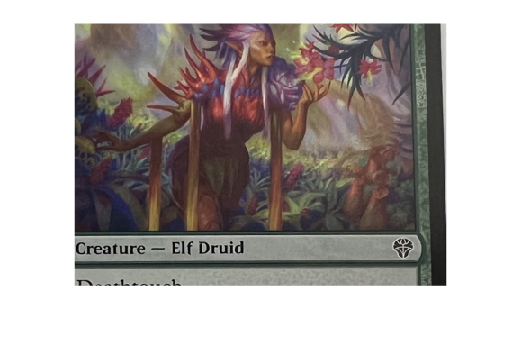


% get
test = imread("https://cards.scryfall.io/art_crop/front/1/4/1465ca9e-a997-4b8c-9677-6c7961f67eba.jpg?1562628773");

% queries
% color
% text
card = croppedImg;
%[card1, ArtCropRect] = imcrop(card);
%normalSize = [680 488];
%card = imresize(card, normalSize);
%imshow(card);
ArtCropRect = [109.510000000000, 243.510000000000, 1286.98000000000, 922.980000000000];
card = imcrop(card, ArtCropRect);

artCropSize = [291 413];
card = imresize(card, artCropSize);
findCard = card;
findCard = rgb2gray(findCard);
imshow(card)

## Get answer DCT

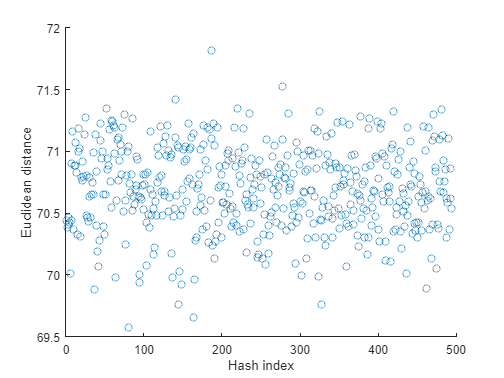

% Choose two hashes to compare (e.g., hashes 1 and 2)
%hash1 = hash_array(1,:);
%hash2 = hash_array(2,:);

% Compute the Hamming distance
%hamming_dist = sum(xor(hash1, hash2));

load('hash.mat');
load('hash_map.mat')
[r,c] = size(hash_array);
num_coeff = 100;

% Choose two hashes to compare (e.g., hashes 1 and 2)
hash1 = hash_array(1,:);
theHash = zeros(2500);

lowestDist = 100000;

%Get card to compare
tempCard = card;
gray_card = rgb2gray(tempCard);
% Apply DCT
dct_img = dct2(gray_card);
% Extract the high-frequency components
num_coeffs = num_coeff;
high_coeffs = dct_img(2:num_coeffs+1, 2:num_coeffs+1);
% Generate the hash
threshold = mean(high_coeffs(:));
hash = high_coeffs > threshold;
hash1 = reshape(hash, 1, []);

distance_values=[];
% iterate through the hash_array
for i=1:r
    hash2 = hash_array(i,:);
    % Compute the Hamming distance
    hamming_dist = sum(xor(hash1, hash2));
    % Compute the Euclidean distance
    euclidean_dist = pdist([hash1; hash2], 'euclidean');
    distance_values= [distance_values euclidean_dist];
    if euclidean_dist < lowestDist
        lowestDist = euclidean_dist;
        theHash = hash2;
    end
end


figure;
scatter(1:r, distance_values);
xlabel('Hash index');
ylabel('Euclidean distance');

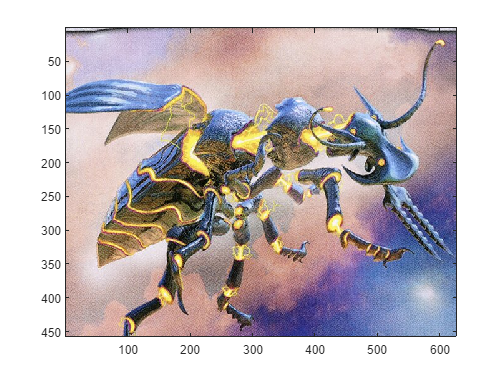


hashKey = sprintf('%d', hash_array(193,:));
cardURL = hash_map(hashKey);
cardFinalImage = imread(cardURL);
imagesc(cardFinalImage);

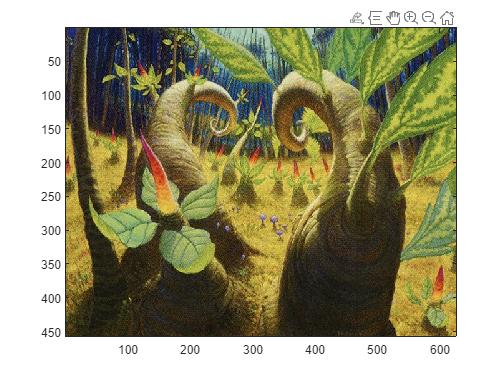


hashKey = sprintf('%d', theHash);
cardURL = hash_map(hashKey);
cardFinalImage = imread(cardURL);
imagesc(cardFinalImage);

## DCT hashing entire json

jsonStr = fileread('mh2set_artcrop.json');
jsonData = jsondecode(jsonStr);

% creating temp files for storage
%tempCard = imread(cell2mat(jsonData(1)));
%gray_card = rgb2gray(tempCard);
hash_array = zeros(length(jsonData), num_coeff*num_coeff);

hash_map = containers.Map;

for i=1:length(jsonData)
    tempCard = imread(cell2mat(jsonData(i)));
    gray_card = rgb2gray(tempCard);
    % INCLUDE LINE BELOW FOR 
    %gray_card = imcrop(gray_card, cardCrop);
    gray_card = imresize(gray_card, artCropSize);
    %gray_card = imcrop(gray_card, [130.5 268.5 1505. 1305]);
    % Apply DCT
    dct_img = dct2(gray_card);

    % Extract the high-frequency components
    num_coeffs = num_coeff;
    high_coeffs = dct_img(2:num_coeffs+1, 2:num_coeffs+1);

    % Generate the hash
    threshold = mean(high_coeffs(:));
    hash = high_coeffs > threshold;
    hash = reshape(hash, 1, []);

    % Store the hash in the hash array                  
    hash_array(i,:) = hash;
    cell2mat(jsonData(i));
    hash_str = sprintf('%d', hash);
    hash_map(hash_str) = cell2mat(jsonData(i));



end
save('hash_map.mat', 'hash_map');
save('hash.mat', 'hash_array');

## testing

%dinner1 = imread("dinner.jpg");
dinner2 = imread("https://cards.scryfall.io/art_crop/front/b/8/b87d368f-e1e0-41ab-9da0-f07c01c8ae38.jpg?1626094006");
imshow(dinner1)
dinner2 = imresize(dinner2, artCropSize);
imshow(dinner2)
%dinner1 = rgb2gray(dinner1);
dinner2 = rgb2gray(dinner2);
points1 = detectSURFFeatures(dinner1);
points2 = detectSURFFeatures(dinner2);
[f1,vpts1] = extractFeatures(dinner1,points1);
[f2,vpts2] = extractFeatures(dinner2,points2);

indexPairs = matchFeatures(f1,f2);
matchedPoints1 = vpts1(indexPairs(:,1));
matchedPoints2 = vpts2(indexPairs(:,2));

figure; showMatchedFeatures(dinner1,dinner2,matchedPoints1,matchedPoints2);
legend('matched points 1','matched points 2');


## SURF Hash entire json

tic;
jsonStr = fileread('dmuset_artcrop.json');
jsonData = jsondecode(jsonStr);
jsonData = reshape(jsonData, 1, []);

hash_arraySURF = cell(1, length(jsonData));

for i=1:length(jsonData)
    tempCard = imread(cell2mat(jsonData(i)));
    gray_card = rgb2gray(tempCard);
    gray_card = imresize(gray_card, artCropSize);

    points = detectSURFFeatures(gray_card);
    [features, valid_points] = extractFeatures(gray_card,points);
    
    % Store the hash in the hash array
    hash_arraySURF{i} = features;
end
arraySURF = vertcat(hash_arraySURF,jsonData);
toc
% 33.92 seconds for arraySURF_mh2set_artcrop
% 34.16 seconds for arraySURF_dmuset_artcrop
% estimated time for artcrop_full is 95 minutes

save('arraySURF_dmuset_artcrop.mat', 'arraySURF');

## SURF get answer

load("arraySURF_dmuset_artcrop.mat")
points1 = detectSURFFeatures(findCard);
[f1,vpts1] = extractFeatures(findCard,points1);

pointsValues =[];
mostPoints = 0;
answerIndex = 1;
for i=1:length(arraySURF)
    indexPairs = matchFeatures(f1, arraySURF{1,i});
    pointsValues = [pointsValues length(indexPairs)];
    if length(indexPairs) > mostPoints
        mostPoints = length(indexPairs);
        index = i;
    end

end


figure;
scatter(1:length(arraySURF), pointsValues);
xlabel('Index');
ylabel('Points Values');

arraySURF(2,index)
cardFinalImage = imread(arraySURF{2,index});
figure;
imagesc(cardFinalImage);